# Examples

figNo = 1;

## Steady-State Solve from LTspice netlist

This section follows the above, but instead using an LTspice file for the converter definition.  The LTspice file follows standard SPICE netlist formatting, but includes additional lines

        .param ts = [1u 50n 1u 50n]

        .param swvec = [1 0 0 0; 0 0 0 0; 0 1 0 0; 0 0 0 0]

which defined the switching times and states.  Like the above case, these will be loaded into the base workspace and can be overwritten later to change their values or, if they are not included in the netlist, can be originally provided from the base workspace.

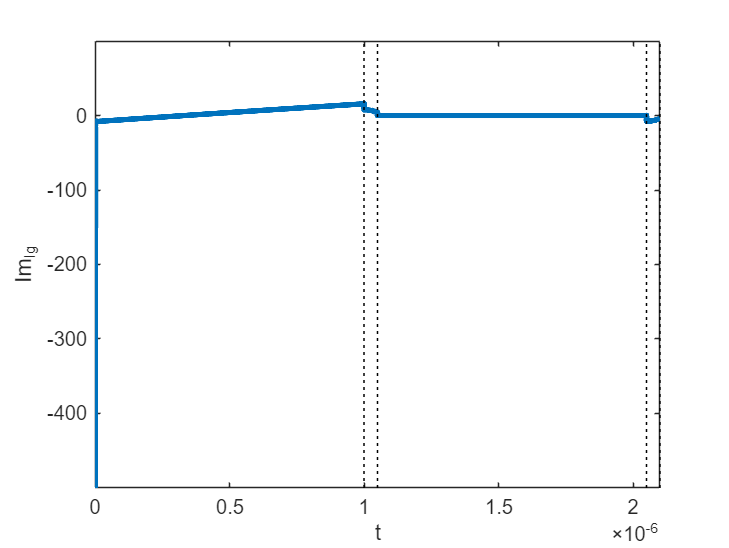

modelfile = 'BuckTest1.net';

pesim = SMPSim();
pesim.initialize(modelfile);                      %swvec, us, and ts are defined 
                                                %in the netlist file and
                                                %loaded during parsing
pesim.steadyState();
pesim.plotAllStates(figNo)
pesim.plotAllOutputs(figNo+1)


figNo = figNo + 2;                             %Increment figure number for future examples

## Steady-State Solve from with dependent States

modelfile = 'AsyncBoost'; PLECsModel = 'Boost_Async';
pesim = loadPLECSTestModel(modelfile, PLECsModel);    %Loads specifically-formatted test converter
if isempty(pesim.As)
    pesim = SMPSim('Boost_Async.net');                %If PLECS isn't installed, load netlist of same converter
end


As before, `steadyState` solves the solution without considering dependent states.  In this case, diode conduction needs to be accounted for in the steady-state solution.  The `hold` command makes sure subsequent call to `plotAllStates` doesn't clear the subplots so that each solution can be compared.

pesim.steadyState();
pesim.plotAllStates(figNo);         %Plot all states BEFORE solving valid diode conduction
hold(gcf().Children,'on');          %hold on, to compare with final solution

findValidSteadyState attempts to solve correct dependent state switching by, alternately, algorithmic determination of switching states and time adjustment based on an error minimization.

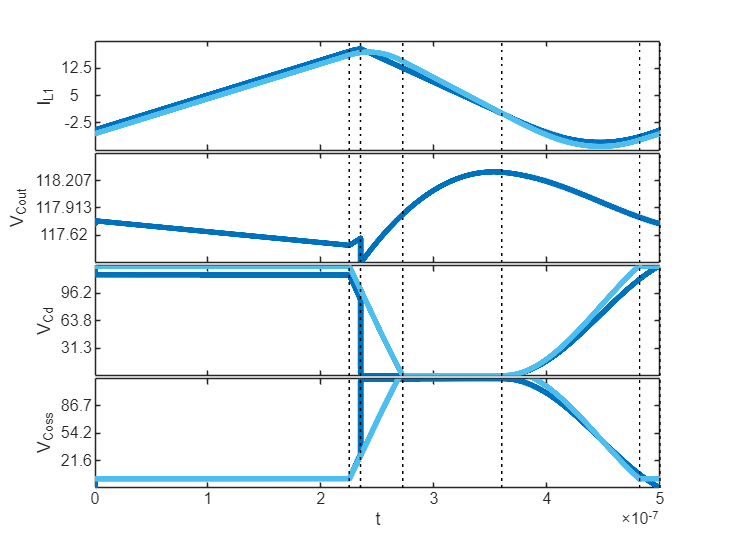

pesim.findValidSteadyState();         %solves correct dependent state behaviour
pesim.plotAllStates(figNo)            %Plot all states AFTER solving valid diode conduction


figNo = figNo + 1;                    %Increment figure number for future examples

## Steady-State Solve from LTspice netlist with dependent States

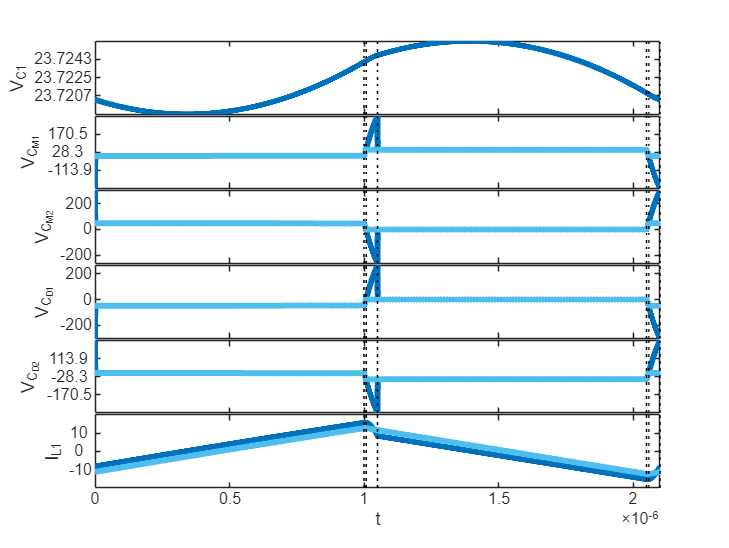

modelfile = 'BuckTest1.net';

pesim = SMPSim(modelfile); 

pesim.plotAllStates(figNo);         %Plot all states BEFORE solving valid diode conduction
hold(gcf().Children,'on');          %hold on, to compare with final solution

pesim.findValidSteadyState();       %solves correct dependent state behaviour
pesim.plotAllStates(figNo)          %Plot all states AFTER solving valid diode conduction

## Example Underdefined PLECS File

If insufficient model details are available in the supplied model and/or the base workspace to fully define the converter topology, and error is thrown which details the missing information.  These variables can be defined in the base workspace programatically, or included in the simulation file explicitly.  The file `DAB_Incomplete `has many elements defined with variable names that are not given scalar values in the base workspace.

if ~isempty(which('plecs'))
    modelfile = 'DAB_Incomplete'; PLECsModel = 'DAB_oneCap';
    
    open_system(modelfile,'loadonly');
    circuitPath = [modelfile '/' PLECsModel];
        
    pesim = SMPSim();
    conv = pesim.converter;
    top = pesim.topology;
        
    try
        top.loadCircuit(circuitPath); %This fails with explanation of missing variables
    catch e
        disp(getReport( e, 'extended', 'hyperlinks', 'on' ) )
    end
end

Error using SMPStopology/loadCircuit (line 143)
Circuit cannot be parsed as either a PLECS or LTSpice file

Error in LiveEditorEvaluationHelperE372926512 (line 47)
        top.loadCircuit(circuitPath); %This fails with explanation of missing variables

Caused by:
    Circuit cannot be parsed as either a PLECS or 

## Finding signals in simulation class

The SMPSim object can be initialized without a switching scheme or inputs.  This is often useful as an intermediate step to determine the locations of e.g. input signals in the input vector ***u ***or switches in the binary switching state vector `swvec.  `This code shows both how to view these assignments in the `stateNames` and other names properties of the `SMPSim` object, and hwo to programatically find a signal's index in the appropriate vector with the `sigLoc` function.

pesim = SMPSim('Boost_Async.net');   

states = pesim.stateNames               %Show signal assignment in the state vector                              

states = 1×4 cell array
    {'Cout'}    {'C_M2'}    {'C_D2'}    {'L1'}


CoutLoc = pesim.sigLoc('Cout','x');   %Location of Cout's voltage in the state vector, x

switches = pesim.switchNames             %Show switch arrangement for swvec

switches = 1×2 cell array
    {'M2'}    {'D2'}



inputs = pesim.inputNames               %Show signal assignment in input vector

inputs = 1×2 cell array
    {'V1'}    {'Vf_D2'}


VdcLoc = pesim.sigLoc('V1','u');    %Location of Vdc's voltage in the input vector, u

outputs = pesim.outputNames              %Show signal assignment in output vector

outputs = 1×4 cell array
    {'Im_M2'}    {'Im_D2'}    {'Vm_M2'}    {'Vm_D2'}


VdsLoc = pesim.sigLoc('Vm_M2','y');  %Location of FETs Vds voltage in the output vector, y


## Getting Discrete Sampling Points

modelfile = 'AsyncBoost'; PLECsModel = 'Boost_Async';
pesim = loadPLECSTestModel(modelfile, PLECsModel);    %Loads specifically-formatted test converter
if isempty(pesim.As)
    pesim = SMPSim('Boost_Async.net');                %If PLECS isn't installed, load netlist of same converter
end

pesim.findValidSteadyState();         %solves correct dependent state behaviour

The `Xs`, `Ys`, and `YsEnd` properties of the SMPSim class give the states and outputs at each of the switching interfaces from the previous steady-state solution.  For a simulation with *ns* states, *nt* time intervals, and *no* outputs, these arrays have sizes

- Xs: *ns* x (*nt*+1) *note*: the first and last column of Xs are the same, as they are the states at *t*=0 and *t*=*Ts*, which are identical in periodic steady-state

- Ys: *no* x (*nt*+1)

- YsEnd: *no* x (*nt*+1)

States cannot change instantaneously, so they will always be continous across the switching boundary.  Outputs, however, are not guaranteed continuous, so both `Ys` and `YsEnd` are included.  `Ys` gives the outputs at the start of each swithcing interval, and `YsEnd` gives the outputs at the end of each subinterval

Xss = pesim.Xs;                       % Get state vector at each switching interface
Yss = pesim.Ys;                       % Get output vector at each switching interface
YssE = pesim.YsEnd;                   % Get output vector at each switching interface before switching occurs

As a further application example, the following finds the Vds of each FET in the circuit just before turning on, and the channel current just before turning off.

if isa(pesim.parser, 'PLECScircuitParser')
    FETLoc = pesim.sigLoc('FET','sw');
    IdsLoc = pesim.sigLoc('FET:Am','y');
    VdsLoc = pesim.sigLoc('Coss','x');
elseif isa(pesim.parser, 'NetlistCircuitParser')
    FETLoc = pesim.sigLoc('M2','sw');
    IdsLoc = pesim.sigLoc('Im_M2','y');
    VdsLoc = pesim.sigLoc('C_M2','x');
end

switchingActions = diff([ pesim.swvec(end,:); pesim.swvec],1);  %Looks at when switching states change
FEToffInt = find(switchingActions(:,FETLoc) == -1); %Find when FET switches off
FETonInt = find(switchingActions(:,FETLoc) == 1); %Find when FET switches on


FET_VdsOn = Xss(VdsLoc, FETonInt)               %Find FET Vds at turn-on instant 

FET_VdsOn = -0.6993

FET_Ioff = YssE(IdsLoc,FEToffInt-1)             %Find FET Ids at turn-off instant (look at end of previous interval to apply correc C and D matrices)

FET_Ioff = 16.1427

## Averaging Signals in Steady-State

modelfile = 'BuckTest1.net';

pesim = SMPSim(modelfile);                  

pesim.findValidSteadyState();         %solves correct dependent state behaviour

The ssAvgs function averages all states and outputs over one full switching period for the current steady-state solution.

[avgXs, avgYs] = pesim.ssAvgs();     %Get average values of all states and outputs in steady-state

The `avgXs` and `avqYs` signals are arranged the same as `Xs` and `Ys`, so can be indexed directly ot indices can be found with `sigLoc` 

VoutLoc = pesim.sigLoc('C1','x');     %Location of Cout's voltage in the state vector, x
ILLoc = pesim.sigLoc('L1','x');       %Location of L's current in the state vector, x
VgLoc = pesim.sigLoc('V1','u');       %Location of Input voltage in the input vector, u
IgLoc = pesim.sigLoc('Im_Ig','y');    %Location of Input current in the output vector, y

Pout = avgXs(VoutLoc)*avgXs(ILLoc); %Output power approximated (for small ripple)
Pin = pesim.u(VgLoc)*avgYs(IgLoc);    %Exact average input power for constant Vg

eta = Pout/Pin*100

eta = 68.7005

## Plotting Specific Signals

modelfile = 'AsyncBoost'; PLECsModel = 'Boost_Async';
pesim = loadPLECSTestModel(modelfile, PLECsModel);    %Loads specifically-formatted test converter
if isempty(pesim.As)
    pesim = SMPSim('Boost_Async.net');                %If PLECS isn't installed, load netlist of same converter
end

pesim.findValidSteadyState();         %solves correct dependent state behaviour

VoutLoc = pesim.sigLoc('Cout','x');   %Location of Cout's voltage in the state vector, x
ILLoc = pesim.sigLoc('L1','x');       %Location of L's current in the state vector, x

`plotAllStates` be default plots all states, but the optional second argument is an array of indices into Xs that specifies which signals to plot.  The same is possible with `plotAllOutputs.`

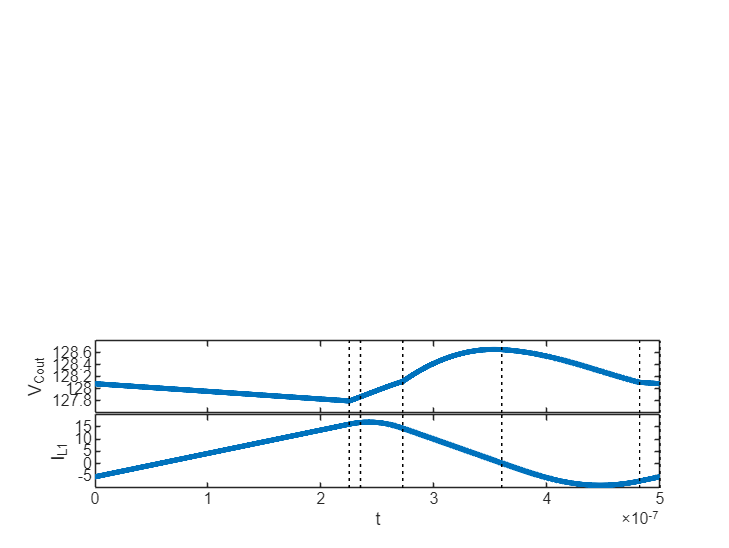

pesim.plotAllStates(figNo,[VoutLoc ILLoc]);   %Plot just IL and Vout


figNo = figNo + 1;                    %Increment figure number for future examples

## Getting Full Steady-State Waveforms

modelfile = 'AsyncBoost'; PLECsModel = 'Boost_Async';
pesim = loadPLECSTestModel(modelfile, PLECsModel);    %Loads specifically-formatted test converter
if isempty(pesim.As)
    pesim = SMPSim('Boost_Async.net');                %If PLECS isn't installed, load netlist of same converter
end

pesim.findValidSteadyState();         %solves correct dependent state behaviour

VoutLoc = pesim.sigLoc('Cout','x');   %Location of Cout's voltage in the state vector, x
ILLoc = pesim.sigLoc('L1','x');       %Location of L's current in the state vector, x

The` SS_WF_Reconstruct() `method is used inside the previous `plotAllStates` and `plotAllOutputs` methods.  It expands the discrete time model into a high resolution time series.  An additional input argument to the `SS_WF_Reconstruct() `function can be used to control the number of points in the reconstructed waveforms.

[xs, t, ys] = pesim.SS_WF_Reconstruct();  %expands full-period time waveforms of states and outputs

Ilrms = sqrt(1/t(end)*trapz(t,xs(ILLoc,:)))

Ilrms = 1.8588

## Variable Input u

The file loaded in this example has the circuit structure shown below.  This can be interpreted as a wireless power transfer converter with coupled coils given by M2.  Here, the rectifier is implemented with switching devices, but no inverter is included.  Instead, the intention is to implement a squarewave voltage source Vg.  

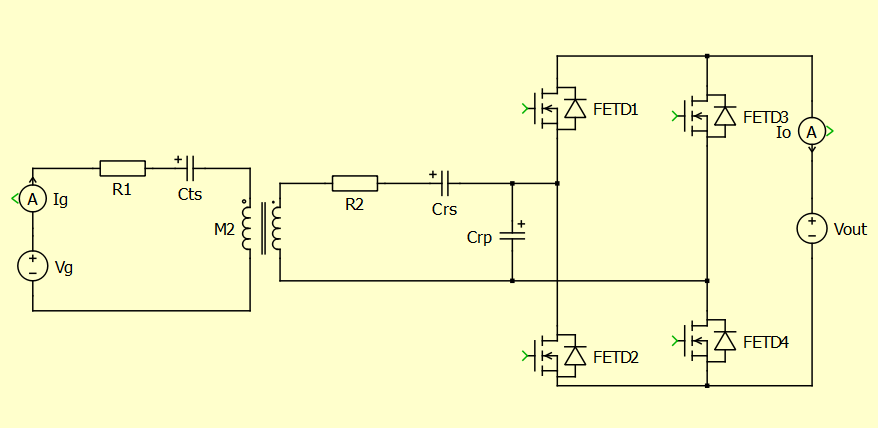

Because the value of the input voltage will show up in the input vector u of the state space description, its value can be changed between discrete intervals.  

modelfile = 'WPT_varyingU'; PLECsModel = 'WPT_SSP';
pesim = loadPLECSTestModel(modelfile, PLECsModel);    %Loads specifically-formatted test converter
if isempty(pesim.As)
    Coss = 0;
    ron = 1e-3;
    pesim = SMPSim('WPT_varyingU.asc');                %If PLECS isn't installed, load netlist of same converter
    pesim.setModulation(swvec,ts);
    pesim.u = u;
end


In this example, u is defined in the simulink file as 

`u= cat(3, [48; 24], [48; 24], [48; 24], [0;24], [-48; 24] , [-48; 24], [-48; 24], [0;24])`

where the input voltage varieds between +/- 48V over the period, and the output dc voltage is always 24V.  The third dimension of the structure is the time interval, corresponding to the timing vector `ts`.

disp(squeeze(pesim.u))    %squeeze used to elimate the third dimension for display

    48    48    48     0   -48   -48   -48     0
    24    24    24    24    24    24    24    24




pesim.findValidSteadyState

ans = 10

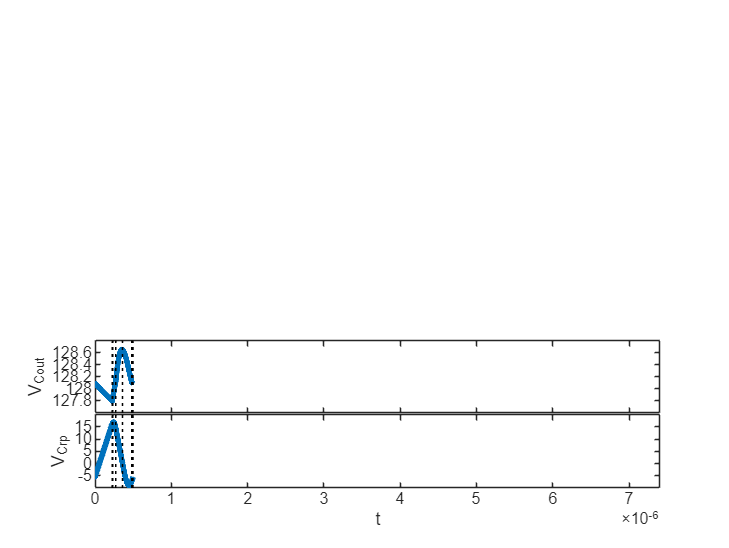

pesim.plotAllStates(figNo)

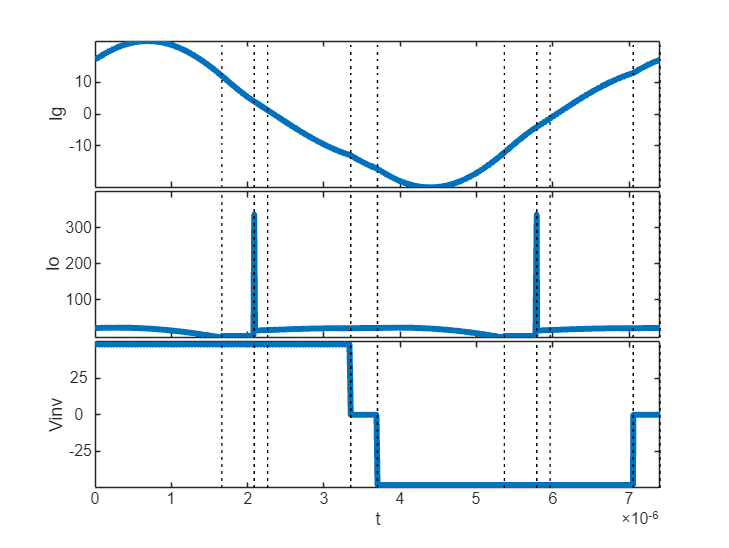

pesim.plotAllOutputs(figNo+1)


figNo = figNo + 2;                    %Increment figure number for future examples

# Supplemental Functions

## Modulation Functions

A few modulation functions are available to speed-up the creation of `ts` and `swvec` parameters for common switching patterns.  `dutyMod()` creates a pair of complementary duty-cycle modulated signals.  The optional `dt` parameter specifies a deadtime.  the plotModwf() function plots the modulation waveform of a `ts` & `swvec` pair for visualization.

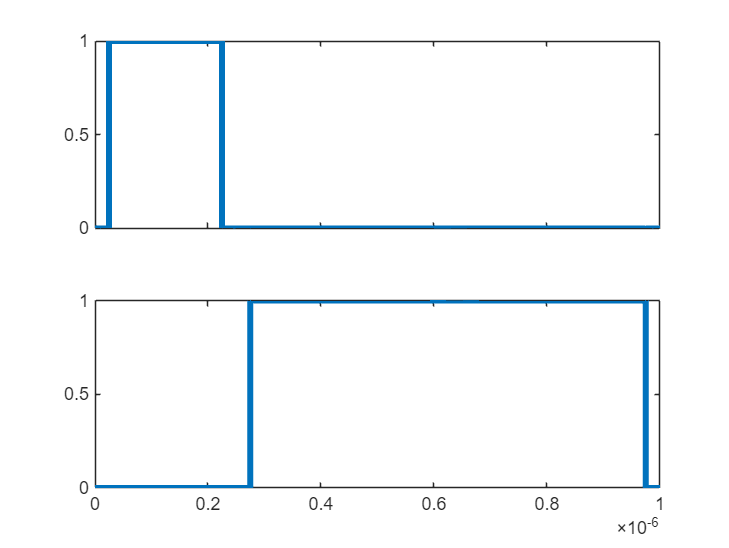

D = 0.25;
Ts = 1e-6;
tdt = Ts/20;
[ts,swvec] = dutyMod(D,Ts,'dt',tdt);

figure(figNo)
plotModWf(ts,swvec);

For more complex waveforms, ts and swvec components can be concatenated in time to make longer multi-period waveforms

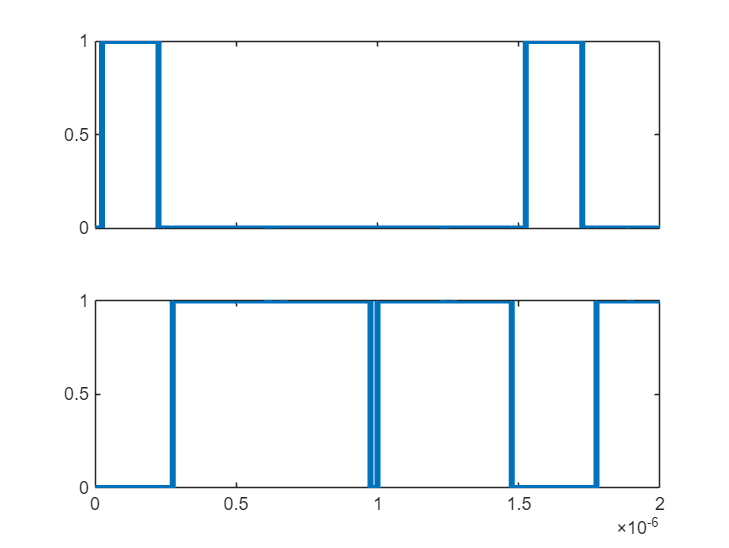

[ts1,swvec1] = dutyMod(D,Ts,'dt',tdt);
[ts2,swvec2] = dutyMod(D,Ts,'dt',tdt, 'phase', Ts/2, 'phaseUnits', 'time');

[ts12,swvec12] = concatMods(ts1,swvec1,ts2,swvec2);
figure(figNo+1)
plotModWf(ts12,swvec12);

 or combined to create more-complex modulation with more than two switching devices

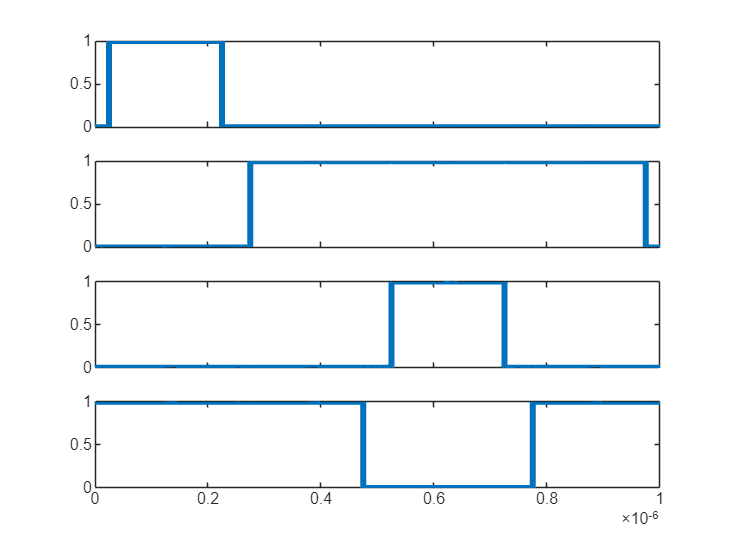

[ts1,swvec1] = dutyMod(D,Ts,'dt',tdt);
[ts2,swvec2] = phaseShiftMod(ts1,swvec1,Ts/2,'phaseUnits','time');

[ts1and2,swvec1and2] = combineMods(ts1,swvec1,[1 2], ts2,swvec2, [3 4]);
figure(figNo+2)
plotModWf(ts1and2,swvec1and2);

`combineModsN()` allows arbitrarily many modulation descriptions to be combined for multi-device converters.

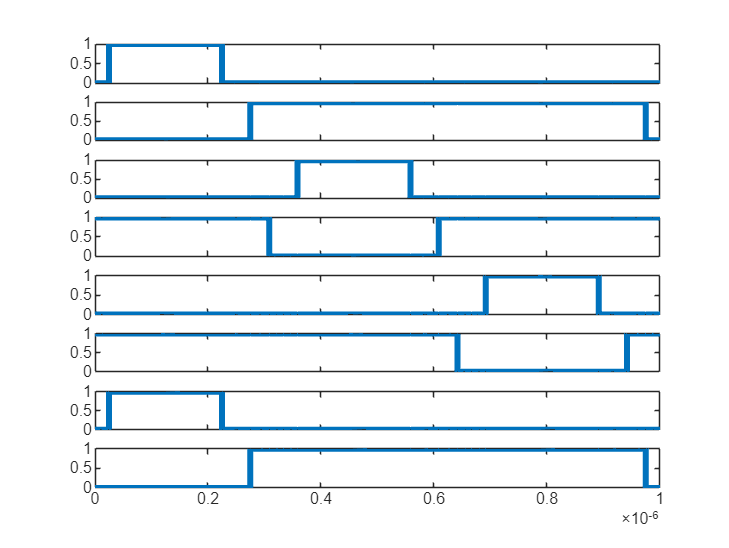

[ts1,swvec1] = dutyMod(D,Ts,'dt',tdt);
[ts2,swvec2] = phaseShiftMod(ts1,swvec1,Ts/3,'phaseUnits','time');
[ts3,swvec3] = phaseShiftMod(ts1,swvec1,2*Ts/3,'phaseUnits','time');

[ts1to3,swvec1to3] = combineModsN(ts1,swvec1,[1 2; 7 8], ts2,swvec2, [3 4], ts3,swvec3, [5 6]);
figure(figNo+3)
plotModWf(ts1to3,swvec1to3);


figNo = figNo + 4;                    %Increment figure number for future examples

# Experimental

## Small signal Models

Discrete time small-signal modeling is well-established.  Given that the circuits are already in suitable form, the `findSSTF()` method finds the transfer function from perturbations to any single time interval to all states at the end of the switching period.  

pesim = SMPSim('Boost_Async.net');             


% Convert boost to small-ripple for comparison to average model
Lf = Lf*10;
Ts = 1e-6;
Coss = 10e-12;
Cd = 10e-12;
ts = [Ts/4, 1e-9, Ts*(3/4)-10e-9, 1e-9];

pesim.updateComponents()
pesim.setModulation(swvec,ts)

pesim.steadyState();         %solves correct dependent state behaviour

Gz = pesim.findSSTF(1);               %solves transfer function from time interval 1 to all states at the end of the period

VoutLoc = pesim.sigLoc('Cout','x');
figure(figNo)

bode(Gz(VoutLoc)*Ts)                %Multiplied by Ts to go from time->duty cycle
hold on;


The below constructs a traditional averaged model of a lossless Boost converter for comparison.  Given the small-ripple design, the discrete time model should match well up to frequencies approaching the Nyquist rate

% Average model of lossless Boost for comparison
s = tf('s');
D = ts(1)/sum(ts);
V = Vg/(1-D);
Gd0 = V/(1-D);
w0 = (1-D)/sqrt(Lf*Co);
Q = (1-D)*RL*sqrt(Co/Lf);
wz = (1-D)^2*RL/Lf;
Gvd = Gd0*(1-s/wz)/(1+s/Q/w0 + (s/w0)^2);

P = bodeoptions;
P.PhaseMatching = 'on';
bode(Gvd,P)
legend('Discrete Time', 'Average Model','Location','southWest');

An additional function,` findAvgModelTF(), creates the average model of a converter in the toolbox.  To match, the non-small-ripple elements are removed, and the deadtimes eliminated.`

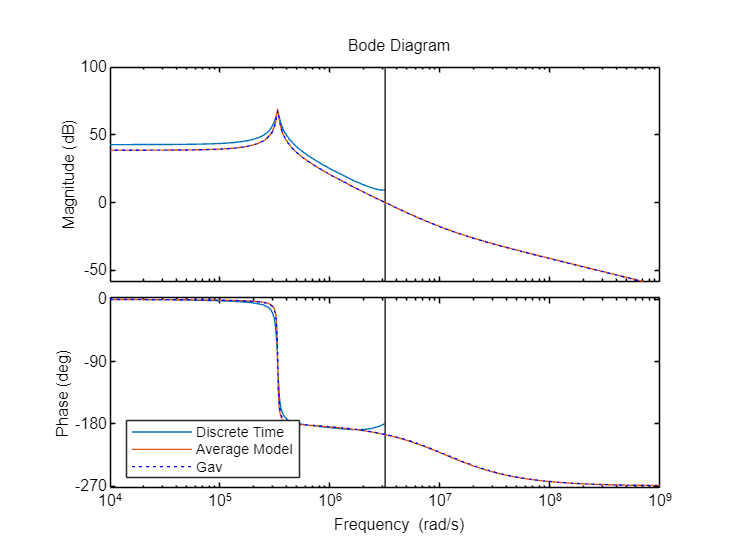

[ts,swvec] = dutyMod(1/4,Ts);
Coss = 0;
Cd = 0;

pesim.updateComponents();
pesim.setModulation(swvec,ts);

pesim.steadyState

Gav = pesim.findAvgModelTF(1,VoutLoc);
bode(Gav,P, ':');       % Matches analytical Gvd


figNo = figNo + 1;                    %Increment figure number for future examples

## Transient Comparison

This example compares step responses of the above average and discrete time models.

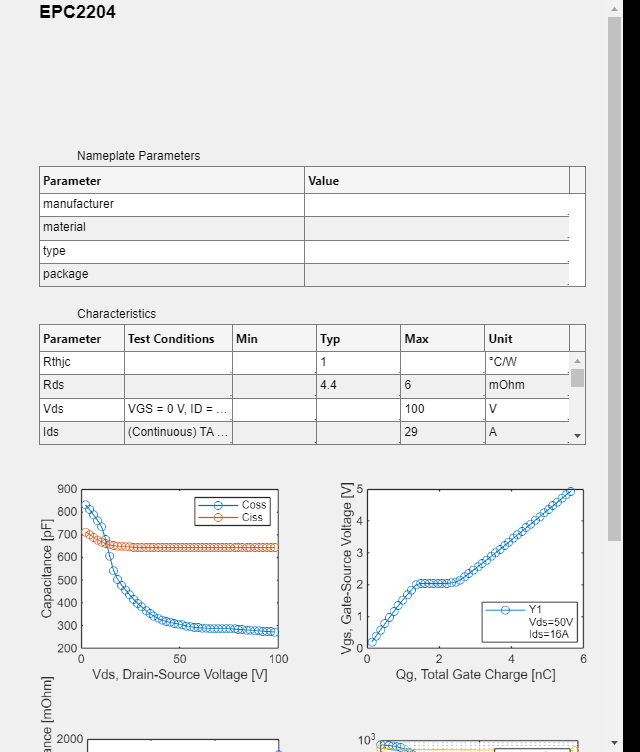

figure (figNo)

Tf = Ts*100;                            %Total time to plot step responses


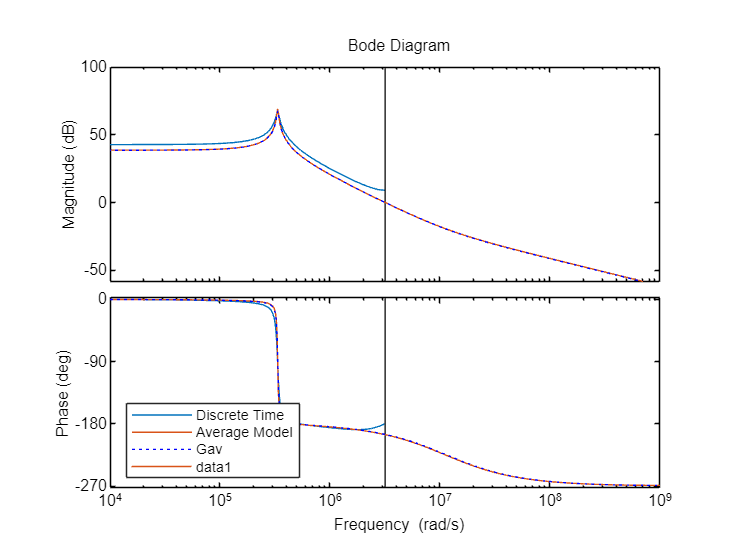

[ts,swvec] = dutyMod(1/4,Ts);           %Redefine modulaiton and solve steady-state op point
pesim.setModulation(swvec,ts);
Xss = pesim.steadyState;

Gav = pesim.findAvgModelTF(1,VoutLoc);  %Solve average model and plot step response
[Y,T] = step(Gav, Tf);
plot(T, Y(:,1)/100, 'LineWidth',2)      %Divided to model a 1% duty cycle step
hold on;

Gz = pesim.findSSTF(1);                 %Solve discrete time model and plot step response

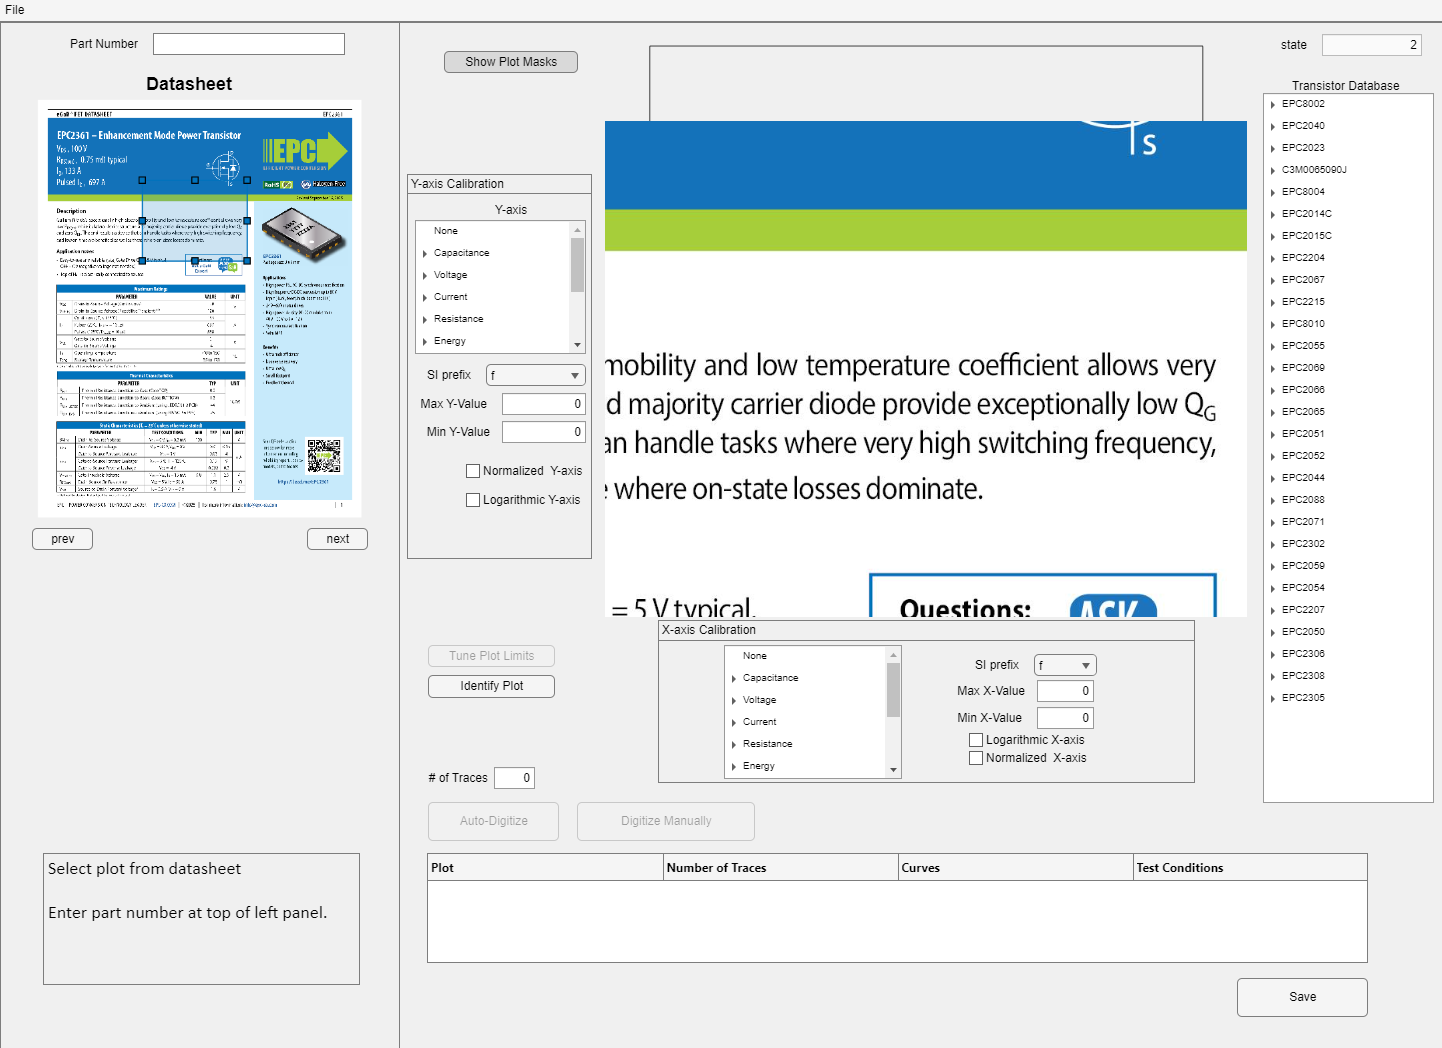

[Y,T] = step(Gz(VoutLoc)*Ts, Tf);
plot(T, Y(:,1)/100, '-o', 'LineWidth',2)


The `simTransient `generates full time-domain waveforms for all states and outputs for the SMPSim object.  It uses the current steady-state solution as a starting point, and the current `swvec` and `ts` as the modulation definition.  By changing the modulation *without re-running *`pesim.steadyState, `the function will plot waveforms for a step response using the old steady-state solution, but new duty cycle.


[ts,swvec] = dutyMod(1/4 + 1/100,Ts);       %Pertub duty cycle by 1%
pesim.setModulation(swvec,ts);

[ xs, t, ys, xd ] = simTransient(pesim, round(Tf/Ts), Xss);  %Get waveforms under new modulation, starting from old steady-state

plot(t,xs(:,1)-Xss(1,1), 'LineWidth',1)     %Subtract off steady-state to compare with small signal models
legend('Average Model', 'Discrete Time SSM', 'DT Transient Simulation')

figNo = figNo + 1;                    %Increment figure number for future examples

## Component Database

Adb = AURAdb();
tdb = Adb.transistors;

tdb(8).datasheet;

Ron = tdb(8).ron.approx;
Coss = tdb(8).Coss.approx;

graphs = tdb(8).graphs;
CplotLoc = find(strcmp({graphs.yLabel}, 'Capacitance'),1,'last');
curveLoc = strcmp(graphs(CplotLoc).dataLabels, 'Coss');

CossV = graphs(CplotLoc).plotData{curveLoc};
plot(CossV(:,1),CossV(:,2));

## GUI for Datasheet digitization

plotDigitizer('https://epc-co.com/epc/portals/0/epc/documents/datasheets/EPC2361_datasheet.pdf')